## Introduction

In this script, i try to plot one-dimetional particle Trajectory

## Data Importing

import parameters

m=1;%just for test
psi=140;%psi=0---> no potential
zeta=300;
H=0.7;
kB=1;
T=1;

import Time interval

delta=0.01;

import Total TIme

Tmax=10;

import Total_experiment_number

Total_experiment_number=5;

## Main loop

initialization

imax=Tmax/delta;
v=zeros(Total_experiment_number,imax+1);
x=zeros(Total_experiment_number,imax+1);
a=zeros(Total_experiment_number,imax+1);

loop

for n=1:Total_experiment_number
    v(n,1)=normrnd(0,(kB*T/m)*0.5);%should be random;
    x(n,1)=0;%no need to be random
    a(n,1)=0;%no need to be random
    BH=wfbm(H,imax+1);
    for i=1:imax
        KH=i:-1:1;
        x(n,i+1)=x(n,i)+v(n,i)*delta;
        v(n,i+1)=v(n,i)+a(n,i)*delta;
        a(n,i+1)=-(zeta/m)*2*H*(2*H-1)*delta^(2*H-2)*((KH.^(2*H-2))*v(n,1:i)')*delta-psi*x(n,i)+(2*zeta*kB*T)^0.5*(BH(i+1)-BH(i))/delta;%ODE
    end

monitoring the progress rate

    progress_rate=n/Total_experiment_number*100;
    if progress_rate==floor(progress_rate)
        disp(['progress rate  ',num2str(progress_rate),' %'])
    end
end

progress rate  20 %
progress rate  40 %
progress rate  60 %
progress rate  80 %
progress rate  100 %


## Output and plotting

averageX=zeros(imax+1,1);
RMSX=zeros(imax+1,1);
for i=1:imax+1
    averageX(i,1)=sum(x(:,i))/Total_experiment_number;
    RMSX(i,1)=sum(x(:,i).^2)/Total_experiment_number-averageX(i,1)^2;
end

plotting

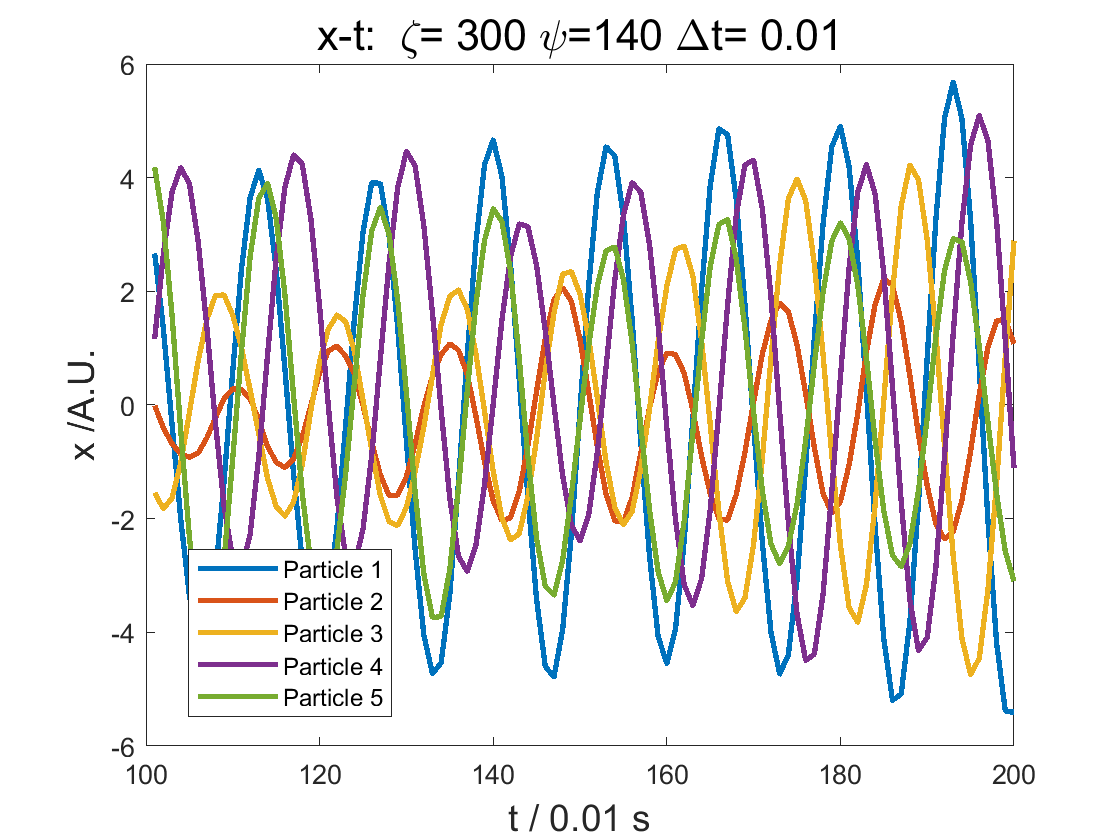

X=101:200;
figure
plot(X,x(1,101:200),X,x(2,101:200),X,x(3,101:200),X,x(4,101:200),X,x(5,101:200),"LineWidth",2)
xlabel(['t / ',num2str(delta),' s'],'FontSize',14)
ylabel('x /A.U.','FontSize',14)
title(['x-t: ',' \zeta= ',num2str(zeta),' \psi=',num2str(psi),' \Deltat= ',num2str(delta)],'FontSize',16)
legend('Particle 1','Particle 2','Particle 3','Particle 4','Particle 5',"Location","best");
saveas(gcf,['v7\image\single_1s~2s','.zeta=',num2str(zeta),'.psi=',num2str(psi),'.jpg'])